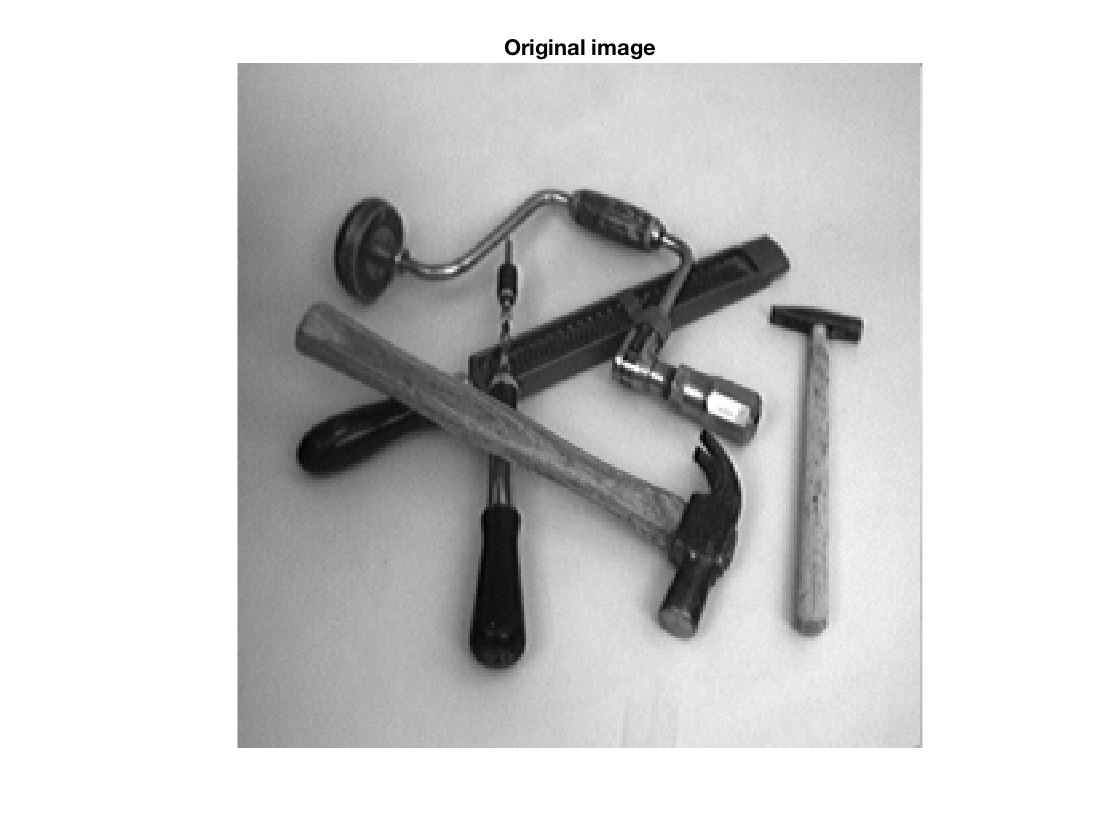

% Q1
tools = few256;
showgrey(tools);
title("Original image");

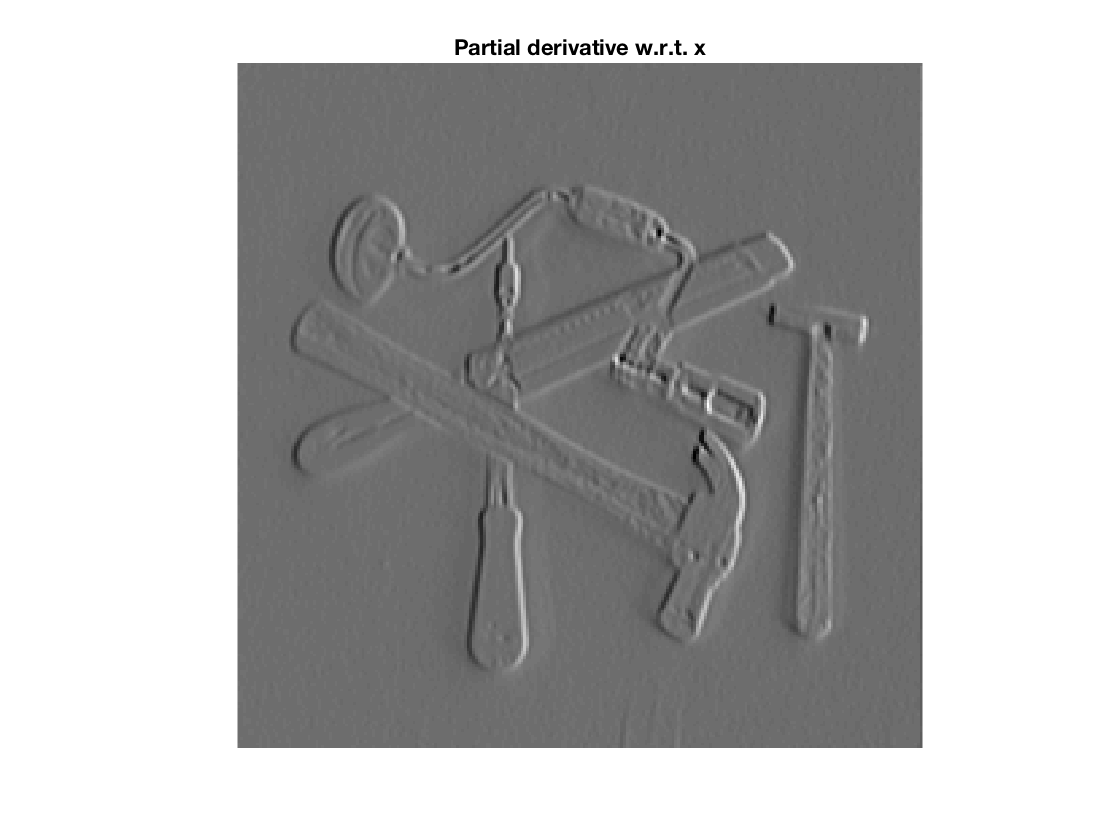


% Sobel (taking flip into account)
deltay = [1 2 1; 0 0 0; -1 -2 -1];
deltax = deltay';

dxtools = conv2(tools, deltax, 'valid');
dytools = conv2(tools, deltay, 'valid');

showgrey(dxtools);
title("Partial derivative w.r.t. x");

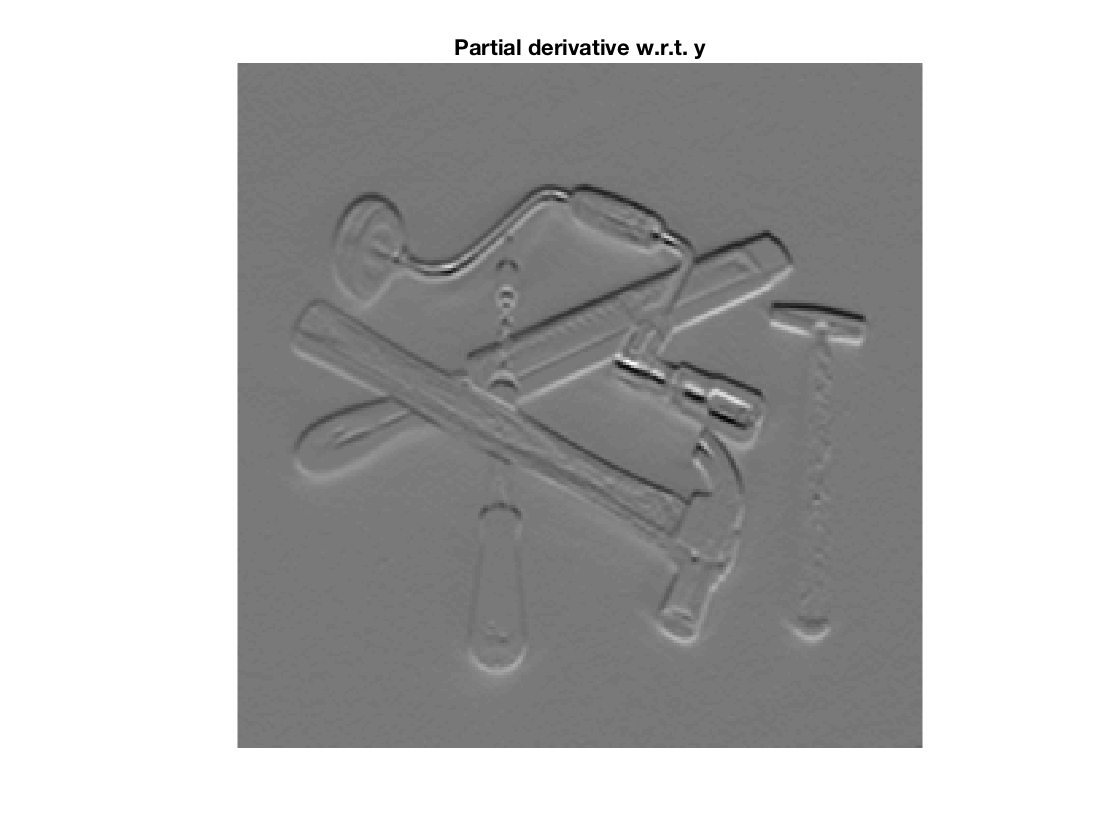


showgrey(dytools);
title("Partial derivative w.r.t. y");


display(size(tools));

   256   256



display(size(dxtools));

   254   254



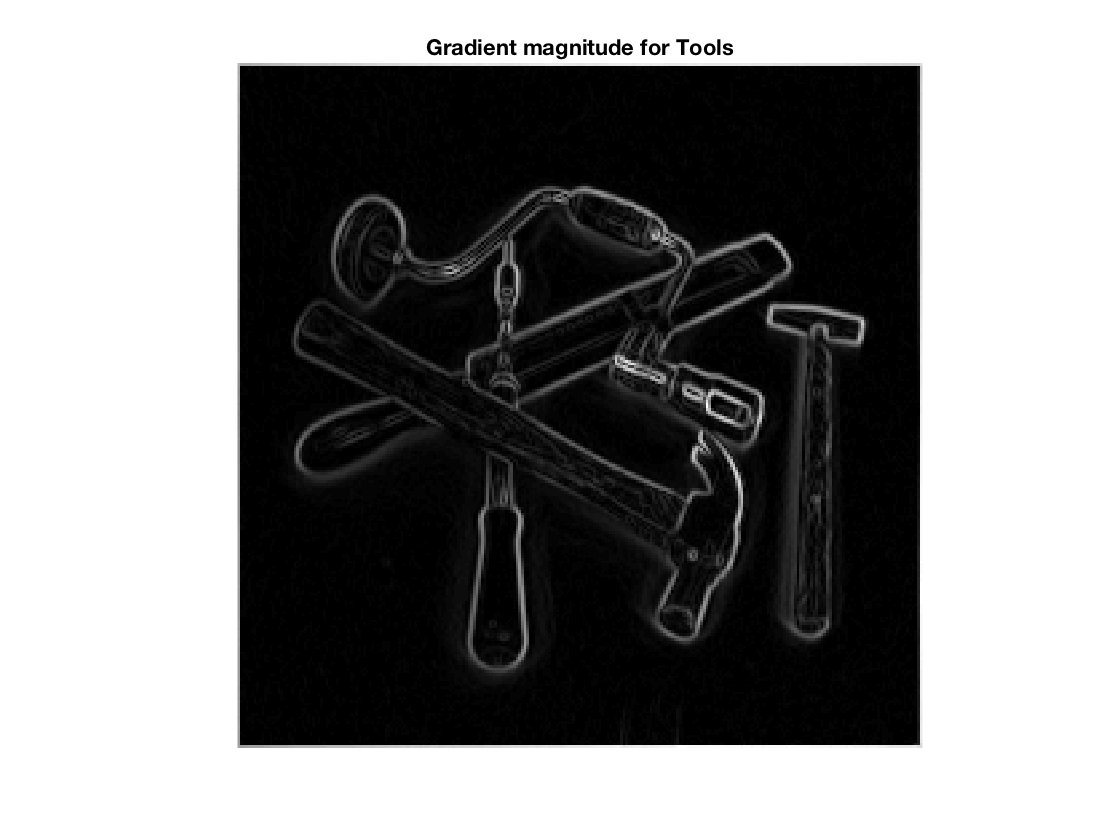

% Q2
house = godthem256;

gradmagntools = sqrt(Lv(tools));
showgrey(gradmagntools);
title("Gradient magnitude for Tools");

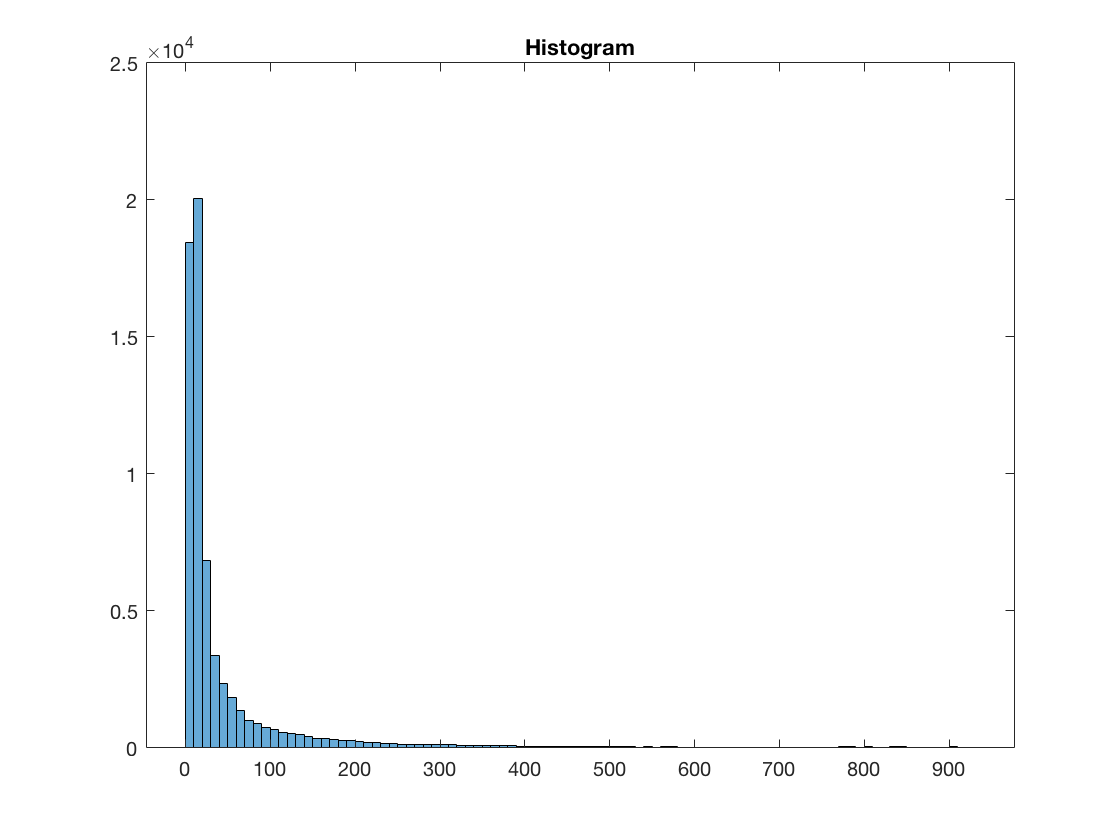

histogram(gradmagntools)
title("Histogram");

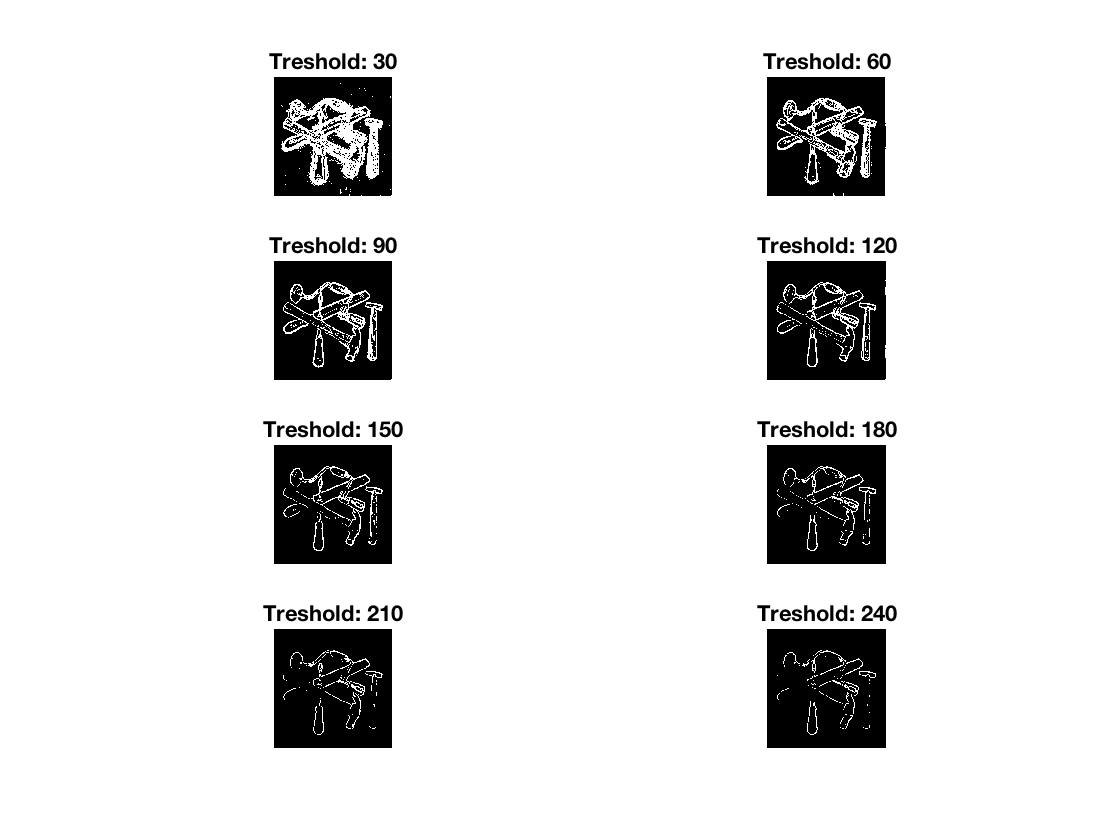


for i = 1:8
    subplot(4,2,i);
    thresh = i * 30;
    showgrey((gradmagntools - thresh) > 0);
    title(sprintf("Treshold: %d", thresh));
end

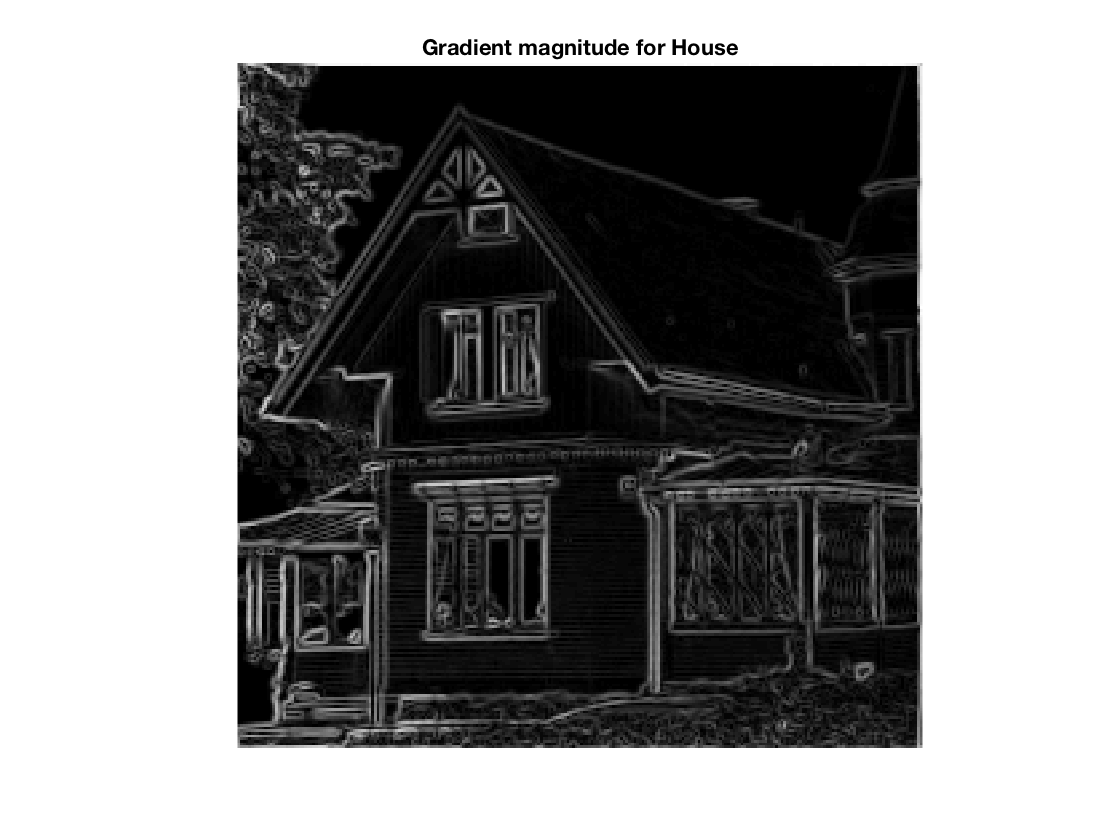

close all

gradmagnhouse = sqrt(Lv(house));
showgrey(gradmagnhouse);
title("Gradient magnitude for House");

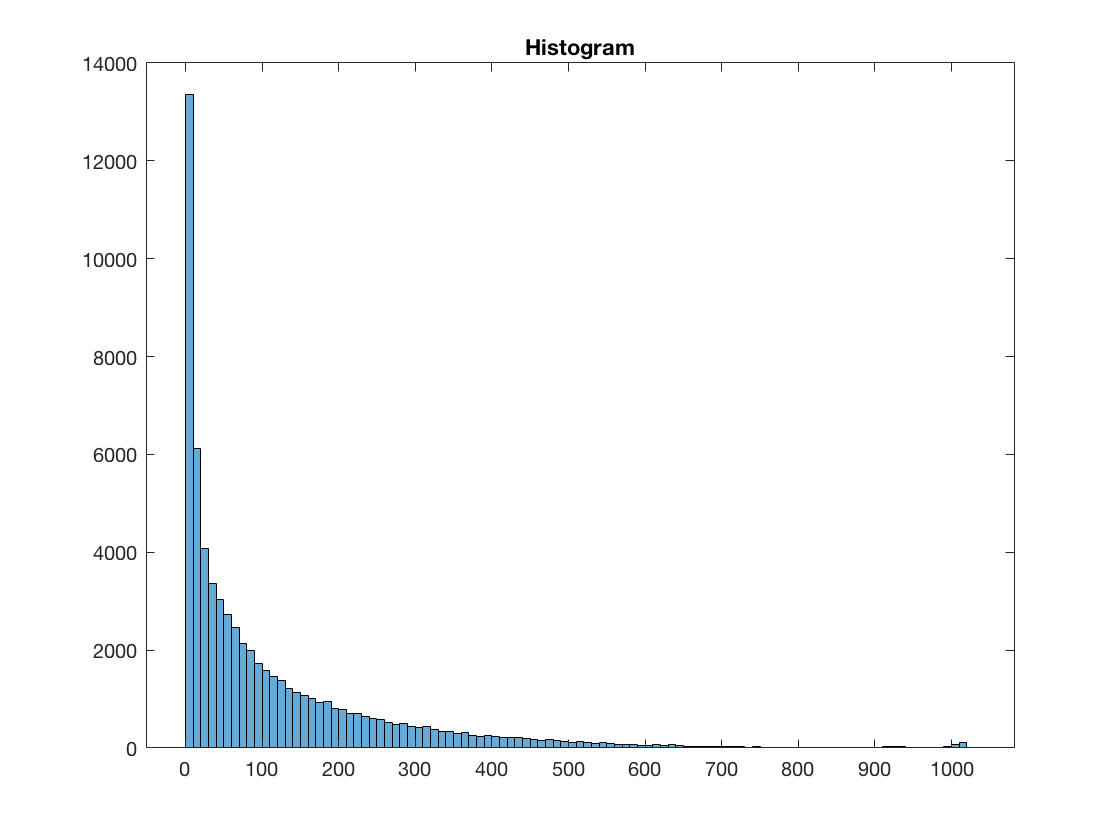

histogram(gradmagnhouse)
title("Histogram");

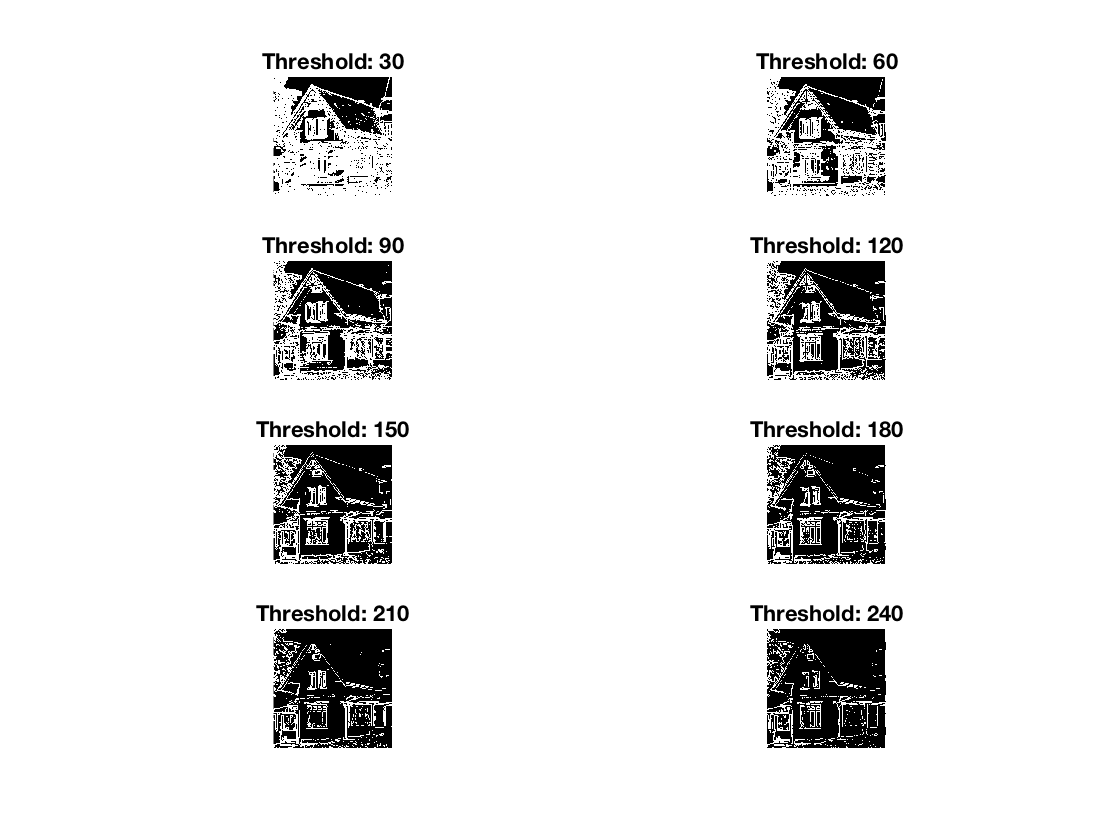


for i = 1:8
    subplot(4,2,i);
    thresh = i * 30;
    showgrey((gradmagnhouse - thresh) > 0);
    title(sprintf("Threshold: %d", thresh));
end

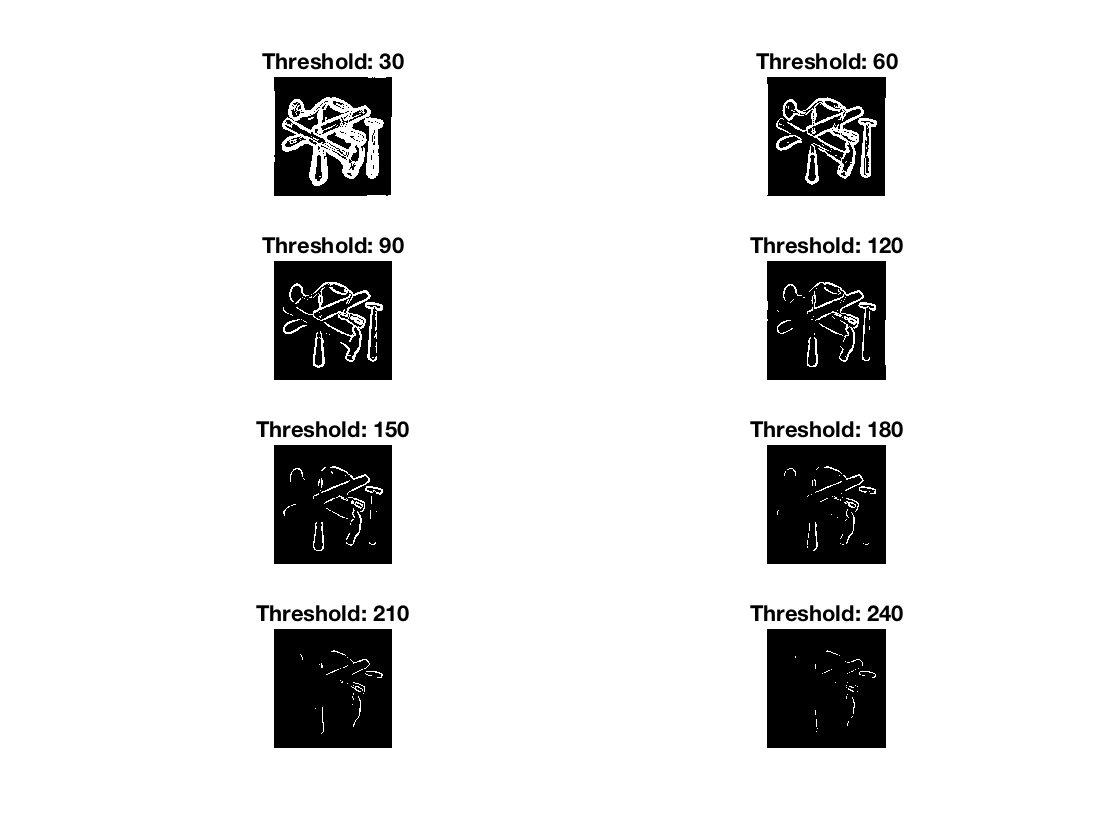

% Q3
close all
tools_smoothed = gaussfft(tools, 2);
% showgrey(tools);
% showgrey(tools_smoothed);
gradmagntools_smoothed = sqrt(Lv(tools_smoothed));
for i = 1:8
    subplot(4,2,i);
    thresh = i * 30;
    showgrey((gradmagntools_smoothed - thresh) > 0);
    title(sprintf("Threshold: %d", thresh));
end

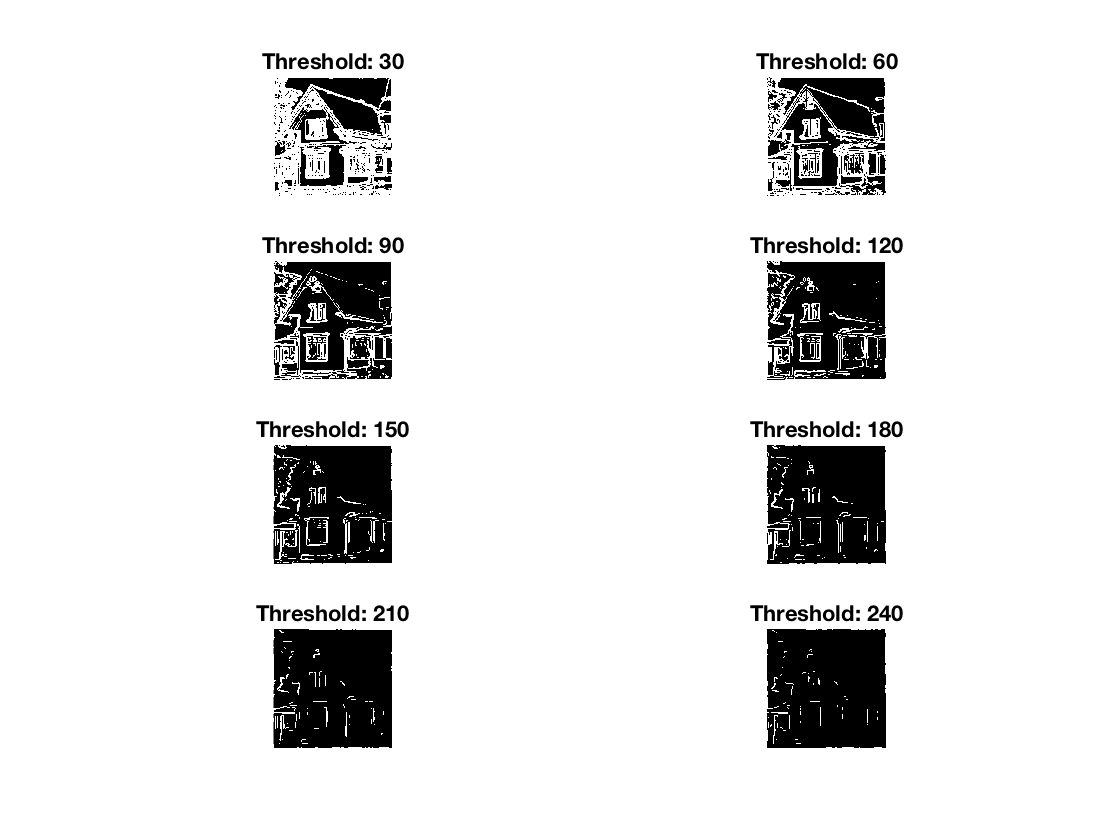

close all
house_smoothed = gaussfft(house, 2);
% showgrey(house);
% showgrey(house_smoothed);
gradmagnhouse_smoothed = sqrt(Lv(house_smoothed));
for i = 1:8
    subplot(4,2,i);
    thresh = i * 30;
    showgrey((gradmagnhouse_smoothed - thresh) > 0);
    title(sprintf("Threshold: %d", thresh));
end

close all
[x y] = meshgrid(-5:5, -5:5);

dxmask = [0 0 0; 0 0 0; -0.5 0 0.5; 0 0 0; 0 0 0];
dymask = dxmask';

dxymask = filter2(dxmask, dymask, 'same');

dxxmask = [0 0 0; 0 0 0; 1 -2 1; 0 0 0; 0 0 0];
dyymask = dxxmask';
dxxxmask = filter2(dxmask, dxxmask, 'same');
dxxymask = filter2(dxxmask, dymask, 'same');

filter2(dxxxmask, x .^3, 'valid')

ans =    98.0000   56.0000   26.0000    8.0000    2.0000    8.0000   26.0000   56.0000   98.0000
   98.0000   56.0000   26.0000    8.0000    2.0000    8.0000   26.0000   56.0000   98.0000
   98.0000   56.0000   26.0000    8.0000    2.0000    8.0000   26.0000   56.0000   98.0000
   98.0000   56.0000   26.0000    8.0000    2.0000    8.0000   26.0000   56.0000   98.0000
   98.0000   56.0000   26.0000    8.0000    2.0000    8.0000   26.0000   56.0000   98.0000
   98.0000   56.0000   26.0000    8.0000    2.0000    8.0000   26.0000   56.0000   98.0000
   98.0000   56.0000   26.0000    8.0000    2.0000    8.0000   26.0000   56.0000   98.0000


filter2(dxxmask, x .^3, 'valid')

ans =    -24   -18   -12    -6     0     6    12    18    24
   -24   -18   -12    -6     0     6    12    18    24
   -24   -18   -12    -6     0     6    12    18    24
   -24   -18   -12    -6     0     6    12    18    24
   -24   -18   -12    -6     0     6    12    18    24
   -24   -18   -12    -6     0     6    12    18    24
   -24   -18   -12    -6     0     6    12    18    24


filter2(dxxymask, x .^2 .* y, 'valid')

ans =     2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000


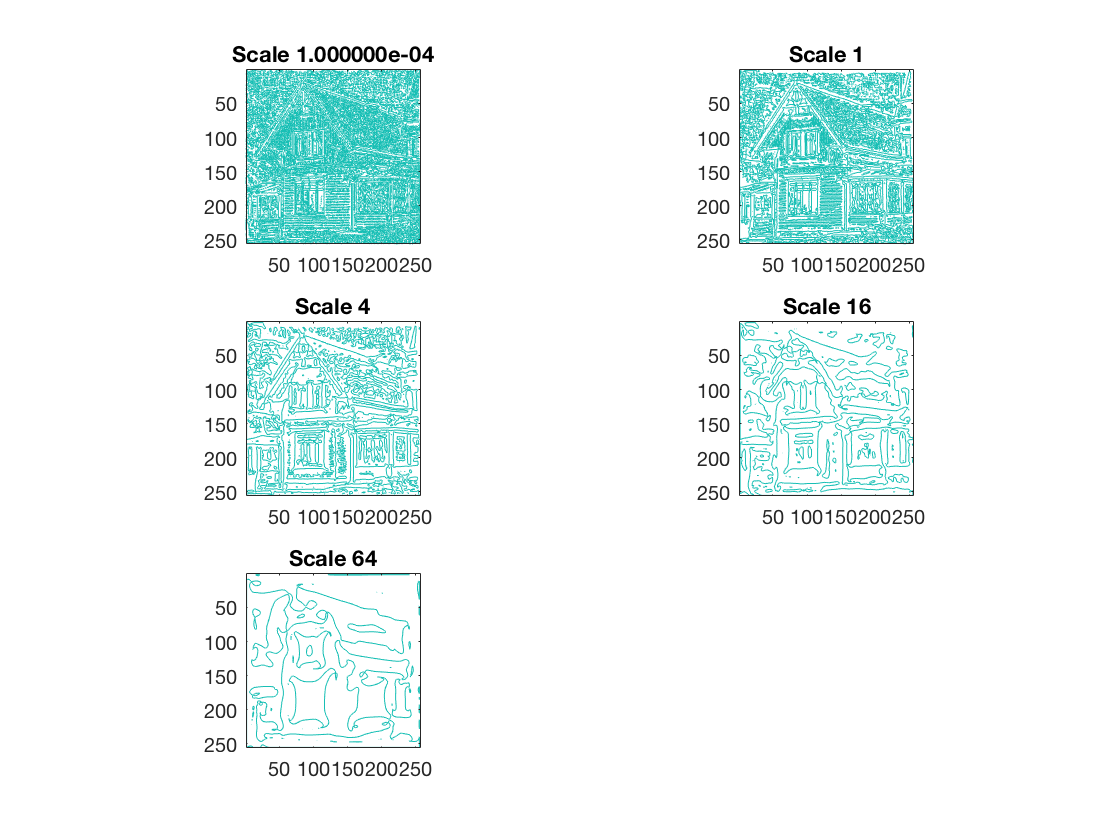

house = godthem256;
% contour(Lvvtilde(discgaussfft(house, 4.0), 'same'), [0 0])
% axis('image')
% axis('ij')

scales = [0.0001 1.0 4.0 16.0 64.0];
for i = 1:5
    subplot(3,2,i);
    contour(Lvvtilde(discgaussfft(house, scales(i)), 'same'), [0 0])
    axis('image')
    axis('ij')
    title(sprintf("Scale %d", scales(i)));
end